# 2-4

clc;
clear all;

## Lets start with creating given signals

Sampling rate is 500HZ and time range is [0 , 2]. A chirp signal is a signal whose frequency varies continuously over time so it is easily definable. Impulse signal is set to have an amplitude of 50 right in the middle of it's range and x_1 is a sinusoidal signal with frequency of 100HZ. Then, x is the sum of three defined signals. Frequency and time domain figures are plotted.

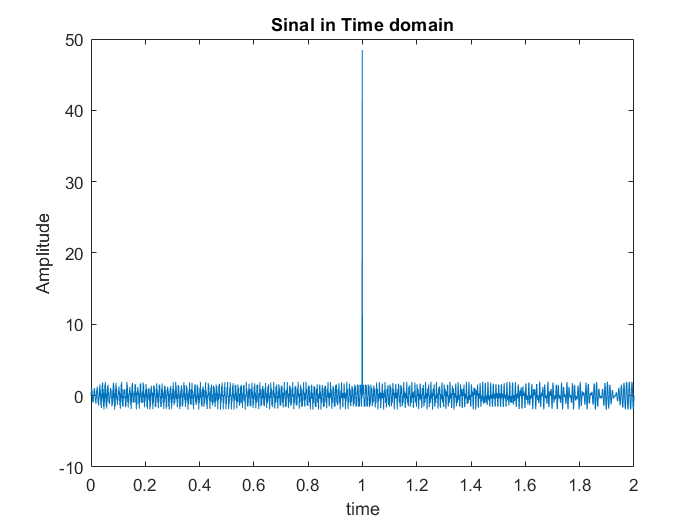

fs=1000;
n=[0:1/fs:2];
x_1=sin(2*pi*100*n);
chirp=sin(2*pi*(-(n-1)*100+400).*n);
impulse=zeros(1,length(n));
impulse(1000)=50;
x= x_1 + chirp + impulse;
f_axis=linspace(-fs/2, fs/2, length(n));

% Illustration

figure;
plot(n,x);
title('Sinal in Time domain')
xlabel('time');
ylabel('Amplitude');

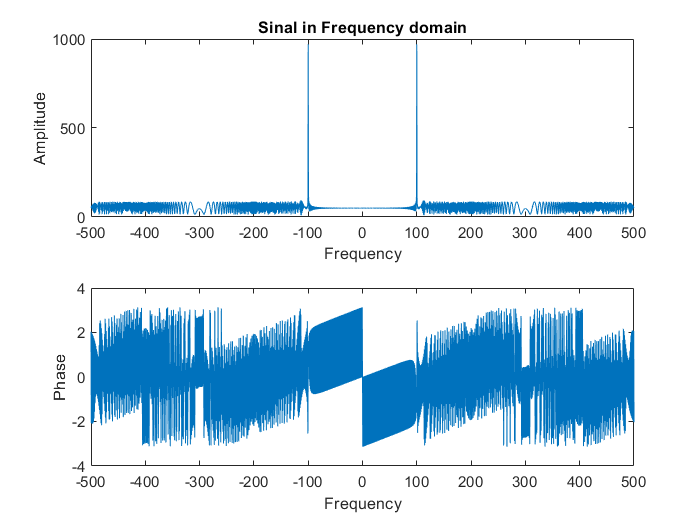


figure;
subplot(2,1,1);
plot(f_axis,abs(fftshift(fft(x))));
xlabel('Frequency');
ylabel('Amplitude');
title('Sinal in Frequency domain')

subplot(2,1,2);
plot(f_axis,angle(fftshift(fft(x))));
xlabel('Frequency');
ylabel('Phase');

## Short time fourier transfor (STFT)

By adjusting overlap and the length of the hamming window we can change the resoloutin of the spectogram. and it is obvious that as we increase the length of the window, higher resoloution in spectogram is gained.

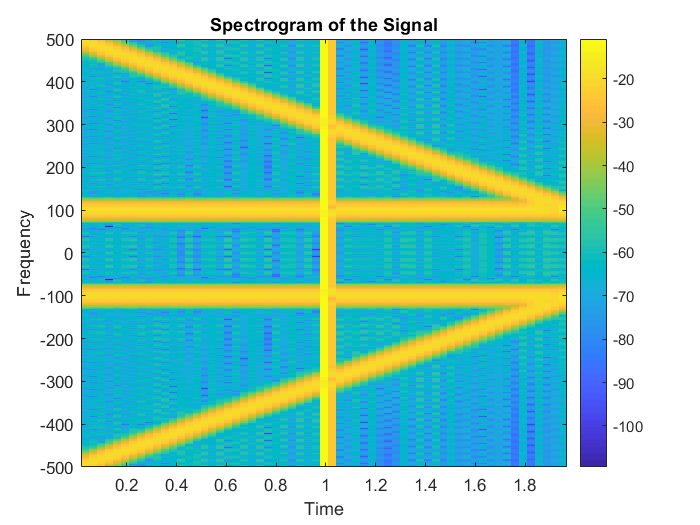

window_length = 64;  % Length of the Hamming window
overlap = window_length/2;  % Overlap between adjacent windows
figure;
spectrogram(x, hamming(window_length), overlap, 511,1000, "centered", 'yaxis');
title('Spectrogram of the Signal');
xlabel('Time');
ylabel('Frequency');
colorbar;

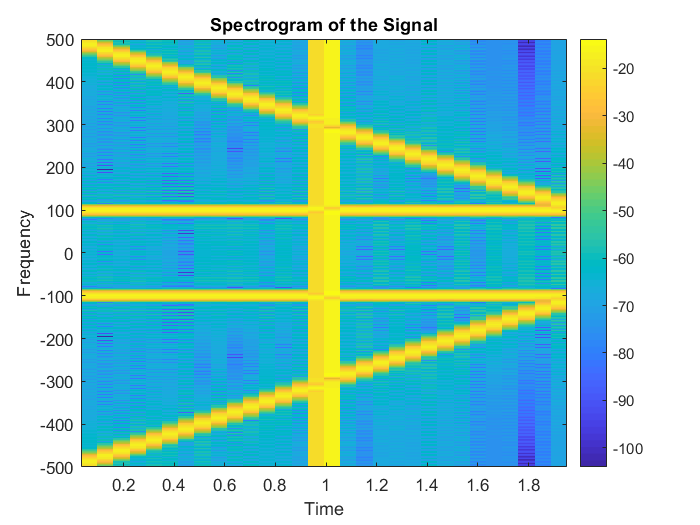


% Window length = 128 overlap=
window_length = 128;  % Length of the Hamming window
overlap = 64;  % Overlap between adjacent windows
figure;
spectrogram(x, hamming(window_length), overlap, 511,1000, "centered", 'yaxis');
title('Spectrogram of the Signal');
xlabel('Time');
ylabel('Frequency');
colorbar;

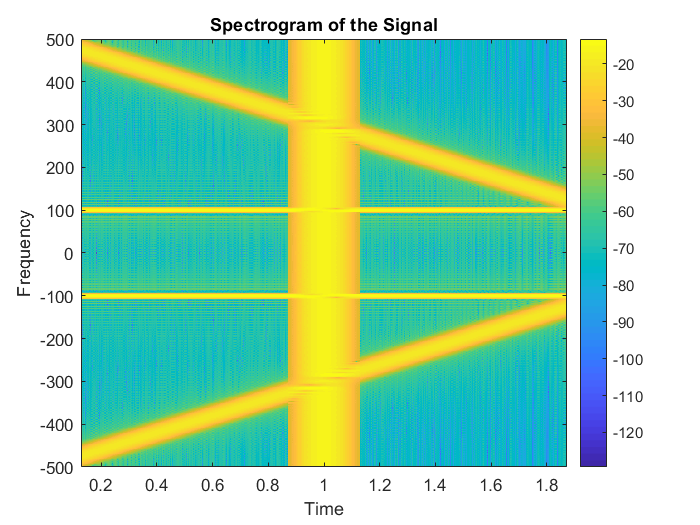


% Window length = 256 overlap=256
window_length = 258;  % Length of the Hamming window
overlap = 256;  % Overlap between adjacent windows
figure;
spectrogram(x, hamming(window_length), overlap, 511,1000, "centered", 'yaxis');
title('Spectrogram of the Signal');
xlabel('Time');
ylabel('Frequency');
colorbar;

## Wavelet Transform

First we create a noisy signal using wnoise function.


N = 8;
loc = linspace(0, 1, 2 ^ N);
Ts = loc(2) - loc(1);
fs = 1 / Ts;
sqrtsnr = 10;
[x, noisy_x] = wnoise('heavy sine', N, sqrtsnr);
figure('Name', 'Heavy Sine Signal vs Heavy Sine Signal with White Noise');
subplot(211);
plot(loc, x, 'LineWidth', 1.5);
title('Heavy Sine Signal');
xlabel('Time');
ylabel('Amplitude');
grid on;
subplot(212);
plot(loc, noisy_x, 'LineWidth', 1.5);
title('Heavy Sine Signal with White Noise');
xlabel('Time');
ylabel('Amplitude');
grid on;

%Fourier domain
f=linspace(-fs/2 , fs/2 , length(x))

f =  -127.5000 -126.5000 -125.5000 -124.5000 -123.5000 -122.5000 -121.5000 -120.5000 -119.5000 -118.5000 -117.5000 -116.5000 -115.5000 -114.5000 -113.5000 -112.5000 -111.5000 -110.5000 -109.5000 -108.5000 -107.5000 -106.5000 -105.5000 -104.5000 -103.5000 -102.5000 -101.5000 -100.5000  -99.5000  -98.5000  -97.5000  -96.5000  -95.5000  -94.5000  -93.5000  -92.5000  -91.5000  -90.5000  -89.5000  -88.5000  -87.5000  -86.5000  -85.5000  -84.5000  -83.5000  -82.5000  -81.5000  -80.5000  -79.5000  -78.5000


figure
subplot(2,1,1)
plot(f,abs(fftshift(fft(x))));
xlabel('freq')
ylabel('amp')
title('Fourier domain of heavy sine')

subplot(2,1,2)
plot(f,abs(fftshift(fft(noisy_x))));
xlabel('freq')
ylabel('amp')
title('Fourier domain of noisy heavy sine');


## Denoising using dwt function

Here we set the wavelet transform to be 5 leveled.

wavelet = 'db2';
level = 5;

% Performing the DWT decomposition
[cA, cD] = dwt(x, wavelet, 'mode', 'symh', 'level', level);
reconstructed_x = idwt(cA, cD, wavelet);
figure('Name', 'Reconstructed Signal');
plot(reconstructed_x, 'LineWidth', 1.5);
title('Reconstructed Signal');
xlabel('Time');
ylabel('Amplitude');
grid on;


### As we see the noisy signal is perfectly reconstructed.